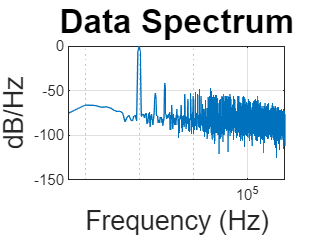

@Freq = 1000.000, SNR = 36.702 dB, SNDR = 35.335 dB, SFDR = 41.389 dB, HD2 = 52.577 and HD3 = 41.389


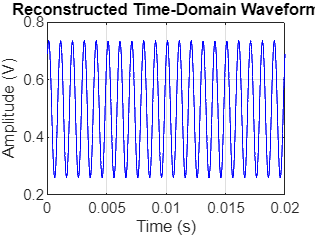

% clearvars
freq_array = readtable('./ADC_Data/shikai-data/11-27-Single-shikai/freq_array.csv');
freq_array = table2array(freq_array);
freq_array = floor(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/shikai-data/11-27-Single-shikai/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
freq_array(1) = 1e3;
for i = 1
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SlowerSample_',num2str(freq_array(i)),'Hz_1000mV---CLK_0MHz_50%.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));

    rising_edge_indices = find(diff(data_EOC) == 1)+1;

    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);

        data_NewCode(k,1) = data_Code_dec(index);

    end
    data_NewDec = data_NewCode;
    % data_NewDec = floor(medfilt1(data_NewCode, 10));
    time_diff = diff(rising_edge_indices);
    Fs=1e6;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =Fs/2;
    sample_size=length(data_NewDec);
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    fs = 1e6;                 % Sampling rate in Hz
    N = length(data_NewDec);                  % Number of samples
    bit_depth = 9;            % ADC bit resolution
    V_min = 0;              % Minimum input voltage
    V_max = 1;               % Maximum input voltage
    
    % Map codes to voltage
    voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    
    % Create time axis
    t = (0:N-1) / fs;
    
    % Plot the reconstructed waveform
    figure;
    plot(t, voltages, 'b');
    title('Reconstructed Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

save('BigSet.mat', 'BigSet');

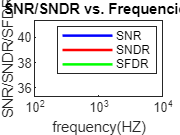

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;

truncate_data = data_NewDec(1:sample_size,1);
max_num = max(truncate_data);
indices = find(truncate_data == max_num);
first_ind = indices(1);
last_ind = indices(end);
truncate_newdata = truncate_data(first_ind:last_ind,1);
% Example: ADC output digital code
adc_output = data_NewDec; % Replace with your ADC output data

% Sampling rate (in Hz, replace with actual sampling frequency)
Fs = 1e6;

% Number of points
N = length(adc_output);

% Perform FFT
fft_result = fft(adc_output);
fft_magnitude = abs(fft_result / N); % Normalize FFT result
fft_magnitude = fft_magnitude(1:N/2+1); % Single-sided spectrum

fft_magnitude(2:end-1) = 2 * fft_magnitude(2:end-1); % Double non-DC components

% Frequency axis
frequencies = (0:(N/2)) * (Fs / N);

% Signal power (assume dominant frequency is the signal)
[~, signal_idx] = max(fft_magnitude); % Find the peak corresponding to the signal
signal_power = fft_magnitude(signal_idx)^2;

% Noise power (total power excluding the signal frequency)
total_power = sum(fft_magnitude.^2);
noise_power = total_power - signal_power;

% Calculate SNR
SNR = 10 * log10(signal_power / noise_power); % SNR in dB

% Display results
disp(['SNR = ' num2str(SNR) ' dB']);

SNR = 6.3826 dB
